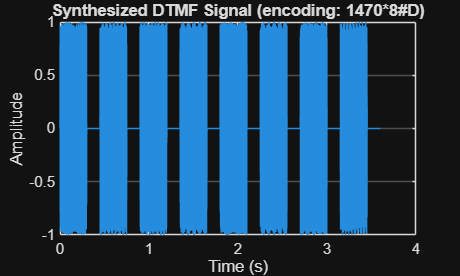

clear; clc; close all;
%% 1) DTMF FREQUENCY TABLE
% Standard telephone keypad frequencies (Hz).
% Each key = one "row" (low) frequency + one "column" (high) frequency.
lowFreqs  = [697 770 852 941];             % rows
highFreqs = [1209 1336 1477 1633];         % columns
% Keypad layout matching the row/column frequencies above:
keypad = ['1' '2' '3' 'A';
          '4' '5' '6' 'B';
          '7' '8' '9' 'C';
          '*' '0' '#' 'D'];

%% 2) GENERATE A TEST DTMF SIGNAL
% Synthesize a test DTMF sequence ----
Fs = 8000;                       % Sampling frequency (Hz) -- standard for telephony
toneDuration = 0.3;              % seconds per key press
silenceDuration = 0.15;          % seconds of silence between key presses
digitsToPlay = '1470*8#D';       % the sequence we'll encode, then try to decode
x = [];
for i = 1:length(digitsToPlay)
    ch = digitsToPlay(i);
    [row, col] = find(keypad == ch);
    tTone = 0 : 1/Fs : toneDuration - 1/Fs;
    tone = sin(2*pi*lowFreqs(row)*tTone) + sin(2*pi*highFreqs(col)*tTone);
    tone = tone / max(abs(tone));   % normalize
    silence = zeros(1, round(silenceDuration*Fs));
    x = [x, tone, silence]; %#ok<AGROW>
end
x = x(:);   % column vector, like a loaded audio file
N = length(x);
t = (0:N-1)/Fs;
figure;
plot(t, x);
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Synthesized DTMF Signal (encoding: %s)', digitsToPlay));
grid on;


%% 3) SEGMENT THE AUDIO INTO INDIVIDUAL TONES
% Find where the signal has real energy (a tone) vs. near-silence,
% so we can isolate and decode each key press separately.
frameSize = round(0.02 * Fs);      % 20 ms frames
frameShift = frameSize;            % no overlap needed for segmentation
numFrames = floor((N - frameSize) / frameShift) + 1;
frameEnergy = zeros(numFrames, 1);
for i = 1:numFrames
    idxStart = (i-1)*frameShift + 1;
    idxEnd = idxStart + frameSize - 1;
    frameEnergy(i) = sum(x(idxStart:idxEnd).^2) / frameSize;
end
energyThreshold = 0.1 * max(frameEnergy);
isTone = frameEnergy > energyThreshold;
% Find contiguous blocks of "tone" frames -> start/end sample indices
toneSegments = [];   % [startSample, endSample]
inTone = false;
for i = 1:numFrames
    if isTone(i) && ~inTone
        segStart = (i-1)*frameShift + 1;
        inTone = true;
    elseif ~isTone(i) && inTone
        segEnd = (i-1)*frameShift;
        toneSegments = [toneSegments; segStart, segEnd]; %#ok<AGROW>
        inTone = false;
    end
end
if inTone
    toneSegments = [toneSegments; segStart, N];
end
fprintf('Detected %d tone segments in the audio.\n', size(toneSegments,1));

Detected 8 tone segments in the audio.



%% 4) FFT + FREQUENCY DETECTION + DIGIT IDENTIFICATION
% For each detected tone segment: run FFT, find the strongest peak
% near each candidate low frequency and each candidate high frequency,
% then pick whichever candidate in each group has the most energy.
% This mimics how real DTMF decoders (e.g. via the Goertzel algorithm)
% check energy at known target frequencies rather than searching blindly.
decodedDigits = '';
searchTolerance = 10;   % Hz -- allow for slight frequency error
figure;
for s = 1:size(toneSegments, 1)
    segX = x(toneSegments(s,1) : toneSegments(s,2));
    segN = length(segX);
    Yf = abs(fft(segX));
    Yf = Yf(1:floor(segN/2));
    freqAxis = (0:floor(segN/2)-1) * (Fs/segN);
    % --- Find energy at each candidate low frequency ---
    lowEnergies = zeros(1, length(lowFreqs));
    for k = 1:length(lowFreqs)
        idx = abs(freqAxis - lowFreqs(k)) <= searchTolerance;
        lowEnergies(k) = max(Yf(idx));
    end
    [~, rowIdx] = max(lowEnergies);
    % --- Find energy at each candidate high frequency ---
    highEnergies = zeros(1, length(highFreqs));
    for k = 1:length(highFreqs)
        idx = abs(freqAxis - highFreqs(k)) <= searchTolerance;
        highEnergies(k) = max(Yf(idx));
    end
    [~, colIdx] = max(highEnergies);
    detectedDigit = keypad(rowIdx, colIdx);
    decodedDigits = [decodedDigits, detectedDigit]; %#ok<AGROW>
    fprintf('Segment %d: low = %d Hz, high = %d Hz -> digit "%s"\n', ...
        s, lowFreqs(rowIdx), highFreqs(colIdx), detectedDigit);
    % Plot this segment's spectrum with detected peaks marked
    if s <= 8   % avoid an overly crowded figure for long sequences
        subplot(2,4,s);
        plot(freqAxis, Yf); hold on;
        plot(lowFreqs(rowIdx), lowEnergies(rowIdx), 'ro', 'MarkerFaceColor', 'r');
        plot(highFreqs(colIdx), highEnergies(colIdx), 'go', 'MarkerFaceColor', 'g');
        xlim([500 2000]);
        xlabel('Hz'); title(sprintf('"%s"', detectedDigit));
        grid on;
    end
end

Segment 1: low = 697 Hz, high = 1209 Hz -> digit "1"
Segment 2: low = 770 Hz, high = 1209 Hz -> digit "4"
Segment 3: low = 852 Hz, high = 1209 Hz -> digit "7"
Segment 4: low = 941 Hz, high = 1336 Hz -> digit "0"
Segment 5: low = 941 Hz, high = 1209 Hz -> digit "*"
Segment 6: low = 852 Hz, high = 1336 Hz -> digit "8"
Segment 7: low = 941 Hz, high = 1477 Hz -> digit "#"
Segment 8: low = 941 Hz, high = 1633 Hz -> digit "D"


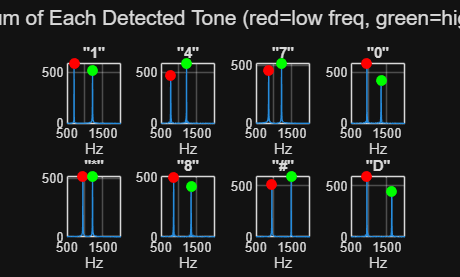

sgtitle('Spectrum of Each Detected Tone (red=low freq, green=high freq)');


%% 5) RESULT
fprintf('\nOriginal sequence : %s\n', digitsToPlay);


Original sequence : 1470*8#D


fprintf('Decoded sequence  : %s\n', decodedDigits);

Decoded sequence  : 1470*8#D


if strcmp(digitsToPlay, decodedDigits)
    disp('SUCCESS: Decoded sequence matches the original.');
else
    disp('MISMATCH: Decoded sequence does NOT match the original.');
end

SUCCESS: Decoded sequence matches the original.


%% ================================================================
%  DONE
% ================================================================
disp('DTMF tone detection complete.');

DTMF tone detection complete.
